# NRG: Full density matrix

Author: [Seung-Sup Lee](https://cqm.snu.ac.kr)

In this tutorial, we will construct "full" density matrix, which is the representation of thermal density matrix in the Anders–Schiller (AS) basis.

## Exercise (a): Complete the function for constructing the full density matrix

There is a function `getRhoFDM_Ex.m`, which is in the same sub-directory with this script. This function is designed to construct the full density matrix. The function is incomplete. Complete the parts enclosed by the comments `TODO (start)` and `TODO (end)`.

Also answer the "Quick Exercise" appear in the demonstration below.

## Reduced density matrix at the impurity site

To verify your implementation, you can run the following script. Below we will analyze the reduced density matrix of the local space covering only the impurity degress of freedom for different system temperatures.

First, run the iterative diagonalization for the SIAM. Here we use the same parameters as those used in the last tutorial.

clear

% Hamiltonian parameters
U = 4e-3; % Coulomb interaction at the impurity
epsd = -U/2; % impurity on-site energy
Delta0 = 2.5e-4; % hybridization strength
D = 1; % half-bandwidh
ozin = [-1;1]*D; % frequency grid to define the hybridization
RhoV2in = [1;1]*(Delta0/pi); % hybridization function on the ozin grid

% NRG parameters
Lambda = 2.5; % discretization parameter
N = 55; % length of the Wilson chain
Nkeep = 300;

% Wilson chain
[ff,gg] = doCLD(ozin,RhoV2in,Lambda,N);

Note that we don't post-process the Wilson chain parameters as we did for the previous tutorials, since the calculations in this tutorial are stable against the (very) small numerical noise that mattered previously.

% Construct local operators
[F,Z,S,I] = getLocalSpace('FermionS');

% Particle number operators
NF = cat(3,contract(conj(F(:,:,1)),3,[1 3],F(:,:,1),3,[1 3]), ...
           contract(conj(F(:,:,2)),3,[1 3],F(:,:,2),3,[1 3]));
       
% Impurity Hamiltonian
H0 = U*(NF(:,:,1)*NF(:,:,2)) + epsd*(NF(:,:,1)+NF(:,:,2));

% ket tensor for the impurity
A0 = getIdentity(1,2,I,2,[1 3 2]); % 1 for dummy leg

% iterative diagonalization
Inrg = NRG_IterDiag(H0,A0,Lambda,ff,F,gg,sum(NF,3),Z,Nkeep);

22-10-22 22:43:09 | NRG: start
22-10-22 22:43:09 | #00/55 : NK=4/4, EK=0/0
22-10-22 22:43:09 | #01/55 : NK=16/16, EK=0.04878/0.04878
22-10-22 22:43:09 | #02/55 : NK=64/64, EK=3.207/3.207
22-10-22 22:43:09 | #03/55 : NK=256/256, EK=6.221/6.221
22-10-22 22:43:09 | #04/55 : NK=328/1024, EK=4.999/13.01
22-10-22 22:43:09 | #05/55 : NK=304/1312, EK=4.681/9.125
22-10-22 22:43:09 | #06/55 : NK=328/1216, EK=5.009/10.56
22-10-22 22:43:09 | #07/55 : NK=304/1312, EK=4.741/9.182
22-10-22 22:43:10 | #08/55 : NK=328/1216, EK=5.038/10.6
22-10-22 22:43:10 | #09/55 : NK=304/1312, EK=4.852/9.268
22-10-22 22:43:10 | #10/55 : NK=328/1216, EK=5.109/10.7
22-10-22 22:43:10 | #11/55 : NK=304/1312, EK=5.048/9.432
22-10-22 22:43:11 | #12/55 : NK=328/1216, EK=5.265/10.92
22-10-22 22:43:11 | #13/55 : NK=300/1312, EK=5.305/9.782
22-10-22 22:43:11 | #14/55 : NK=328/1200, EK=5.554/11.22
22-10-22 22:43:11 | #15/55 : NK=320/1312, EK=5.712/10.54
22-10-22 22:43:11 | #16/55 : NK=306/1280, EK=5.863/11.25
22-10-22 22:43:12 

A conceptual advantages of the full density matrix scheme is that one can choose arbitrary temperatures, as long as they are sufficiently larger than the energy scale for the last Wilson chain site, without the need of a free parameter. Meanwhile, the conventional NRG scheme requires temperatures be of type $\beta_0 \Lambda^{-n/2}$ (up to a prefactor), where $\beta_0$ is an arbitrary free parameter.

Ts = 10.^(1:-0.5:-7).'; % temperature range
RK = cell(numel(Ts),1); % cell array to conatin the reduced density matrices

for itT = (1:numel(Ts))
    Inrg = getRhoFDM_Ex (Inrg,Ts(itT)); % construct FDM
    RK{itT} = Inrg.RK{1};
end

22-10-22 22:43:20 | Construct full density matrix @ T = 10.
Elapsed time: 1.345s, CPU time: 8.67s, Avg # of cores: 6.447
22-10-22 22:43:21 | Construct full density matrix @ T = 3.162.
Elapsed time: 1.317s, CPU time: 8.47s, Avg # of cores: 6.434
22-10-22 22:43:23 | Construct full density matrix @ T = 1.
Elapsed time: 1.319s, CPU time: 8.46s, Avg # of cores: 6.415
22-10-22 22:43:24 | Construct full density matrix @ T = 0.3162.
Elapsed time: 1.363s, CPU time: 8.69s, Avg # of cores: 6.378
22-10-22 22:43:25 | Construct full density matrix @ T = 0.1.
Elapsed time: 1.346s, CPU time: 8.55s, Avg # of cores: 6.351
22-10-22 22:43:27 | Construct full density matrix @ T = 0.03162.
Elapsed time: 1.331s, CPU time: 8.54s, Avg # of cores: 6.419
22-10-22 22:43:28 | Construct full density matrix @ T = 0.01.
Elapsed time: 1.409s, CPU time: 9.07s, Avg # of cores: 6.439
22-10-22 22:43:29 | Construct full density matrix @ T = 0.003162.
Elapsed time: 1.51s, CPU time: 10.11s, Avg # of cores: 6.696
22-10-22 22:

Let's check whether the reduced density matrices are diagonal. (**Quick Exercise:** Why is the reduced density matrix at the impurity site diagonal?)

disp(max(cellfun(@(x) max(max(abs(x - diag(diag(x))))), RK)));

   8.9530e-13



This value is on the order of numerical precision, so we confirm the diagonality of the matrices.

Also, we can check whether the reduced density matrices respect the particle-hole symmetry. According to our convention used in `getLocalSpace.m` (refer to the documentation in the function file, for details), the basis of the impurity space is $\{ | 0 \rangle , \hat{d}_{\uparrow}^\dagger | 0 \rangle , \hat{d}_{\downarrow}^\dagger | 0 \rangle , \hat{d}_{\downarrow}^\dagger \hat{d}_{\uparrow}^\dagger | 0 \rangle \}$, where $| 0 \rangle$ denotes the vacuum state. So we can check the particle-hole symmetry as follows:

disp(max(cellfun(@(x) max(abs(flipud(diag(x))-diag(x))), RK)));

   5.0682e-14



Again, this value is on the order of numerical precision, so we confirm the symmetry.

## Double occupation vs. temperature

Let's compute the double occupation $\langle \hat{n}_{d \uparrow} \hat{n}_{d\downarrow} \rangle$ at the impurity, where $\hat{n}_{d\sigma} = \hat{d}_{\sigma}^\dagger \hat{d}_{\sigma}$ is the number operator for spin-$\sigma$ electron at the impurity site. It can be measured by contracting the double occupation operator $\hat{n}_{d \uparrow} \hat{n}_{d\downarrow}$ and the reduced density matrices.

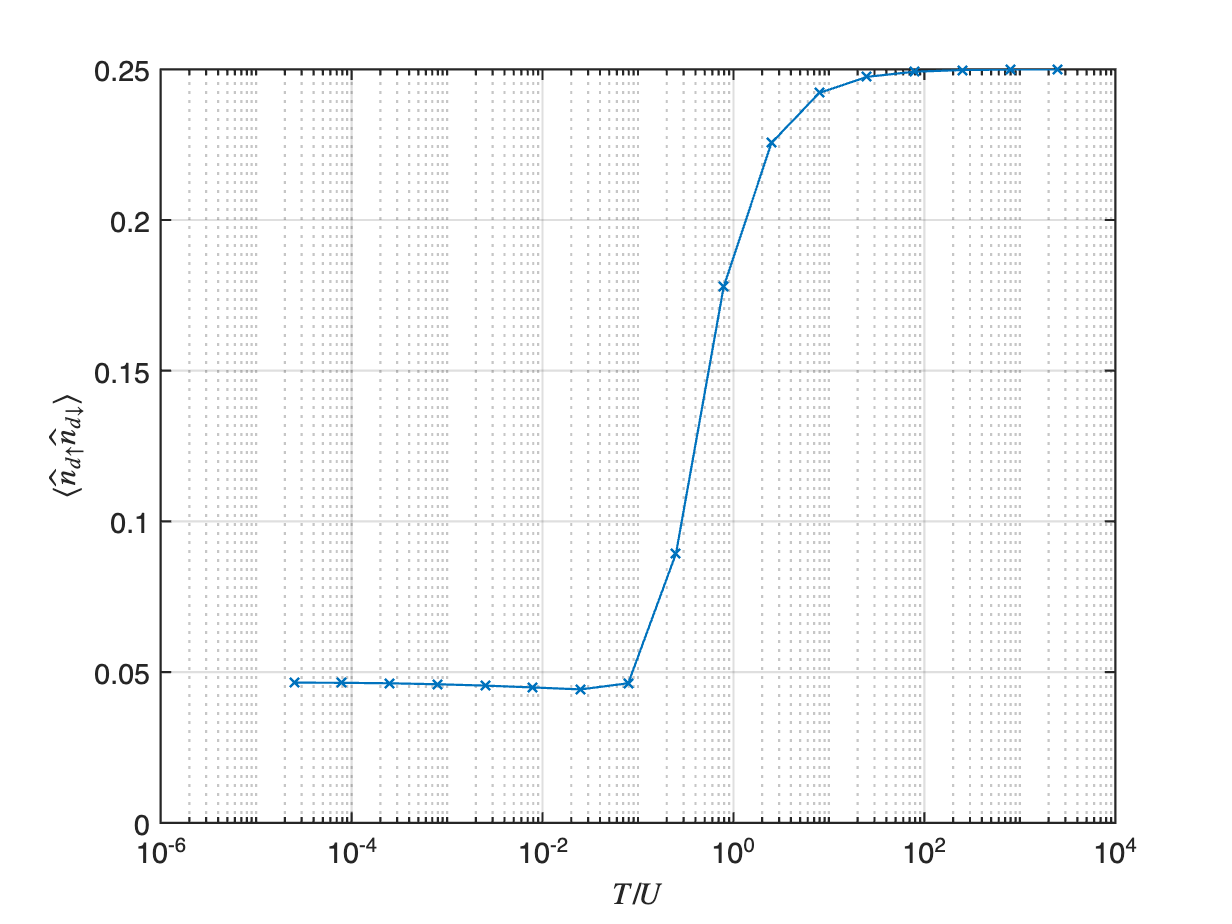

Dop = NF(:,:,1)*NF(:,:,2); % operator measuring for double occupation
Dvals = zeros(size(Ts)); % expectation value of Dop

for itT = (1:numel(Ts))
    % contract the reduced density matrix at the impurity 
    % with the operator
    Dvals(itT) = trace(updateLeft([],[], ...
        Inrg.AK{1},Dop,2,Inrg.AK{1})*RK{itT});
end

figure;
semilogx(Ts/U,Dvals,'Marker','x','LineWidth',1);
set(gca,'FontSize',13,'LineWidth',1);
xlabel('$T/U$','Interpreter','latex');
ylabel('$\langle \hat{n}_{d \uparrow} \hat{n}_{d \downarrow} \rangle$', ...
    'Interpreter','latex');
grid on;

We see that the double occupation $\langle \hat{n}_{d \uparrow} \hat{n}_{d \downarrow} \rangle$ decreases with decreasing $T$ with a crossover around $T \sim U$. On the other hand, the double occupation saturates in the low-temperature regime $T \ll U$: it means that the charge fluctuation is "frozen" by low temperature.

(**Quick Exercise 2:** Why is the double occupation close to 0.25 at highest temperatures?)